Definizione del **numeratore** e del **denominatore** della **FdT**.

num = 1;
den = conv([1 0],[1 1]); 

sys = tf(num,den) % sys = 1/(s(s+1))


sys =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.
Model Properties


Calcolo dei **poli** del sistema dinamico.

pole(sys)

ans =      0
    -1


Tracciamento del **diagramma di Bode**.

- Dovuto al polo nell'origine, il modulo diminuisce di 20 dB/dec. 

- Alla pulsazione 𝜔→1, il modulo scende di 40 dB/dec dovuto al polo reale.

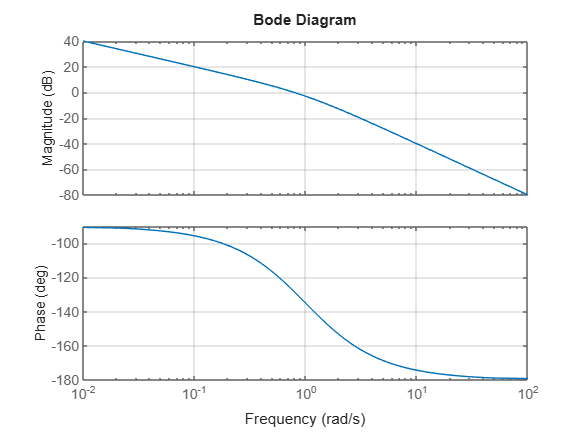

bode(sys);
grid on

Calcolo di** modulo** e** fase** per diversi valori di **w.**

[mag,phase,wout] = bode(sys);